# DSP Project Phase II

## Ashkan Yousefnia                                                                                                                                                    

## Main code

#### qustion 7:

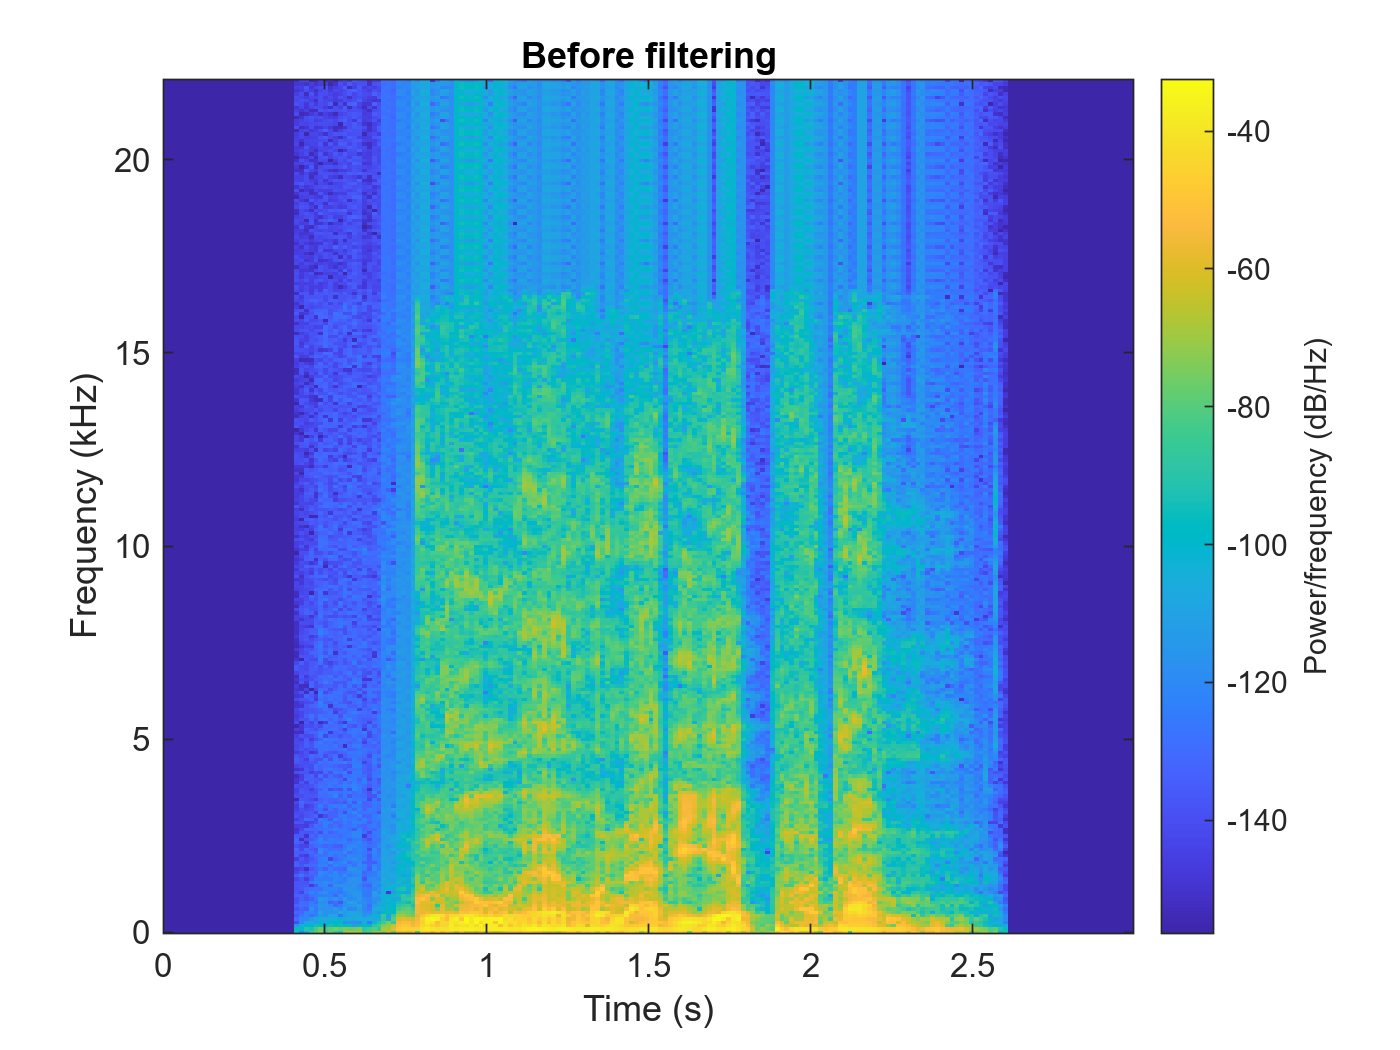

 %plot(linspace(0, (10000/2), 513), filterBank'), title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
signal = audioread("dataset\train\s8.wav");


filter_nums = 40;
fft_lenght = 512;
fs = 44100;
window_lenght_sec = 0.015;
window_lenght = floor(44100*window_lenght_sec);
overlap_percent = 40;
ceps_num = 26;
id=8;

spectrogram(signal, window_lenght , floor((length(window_lenght)*overlap_percent)/100), fft_lenght, fs, 'yaxis');
title('Before filtering');

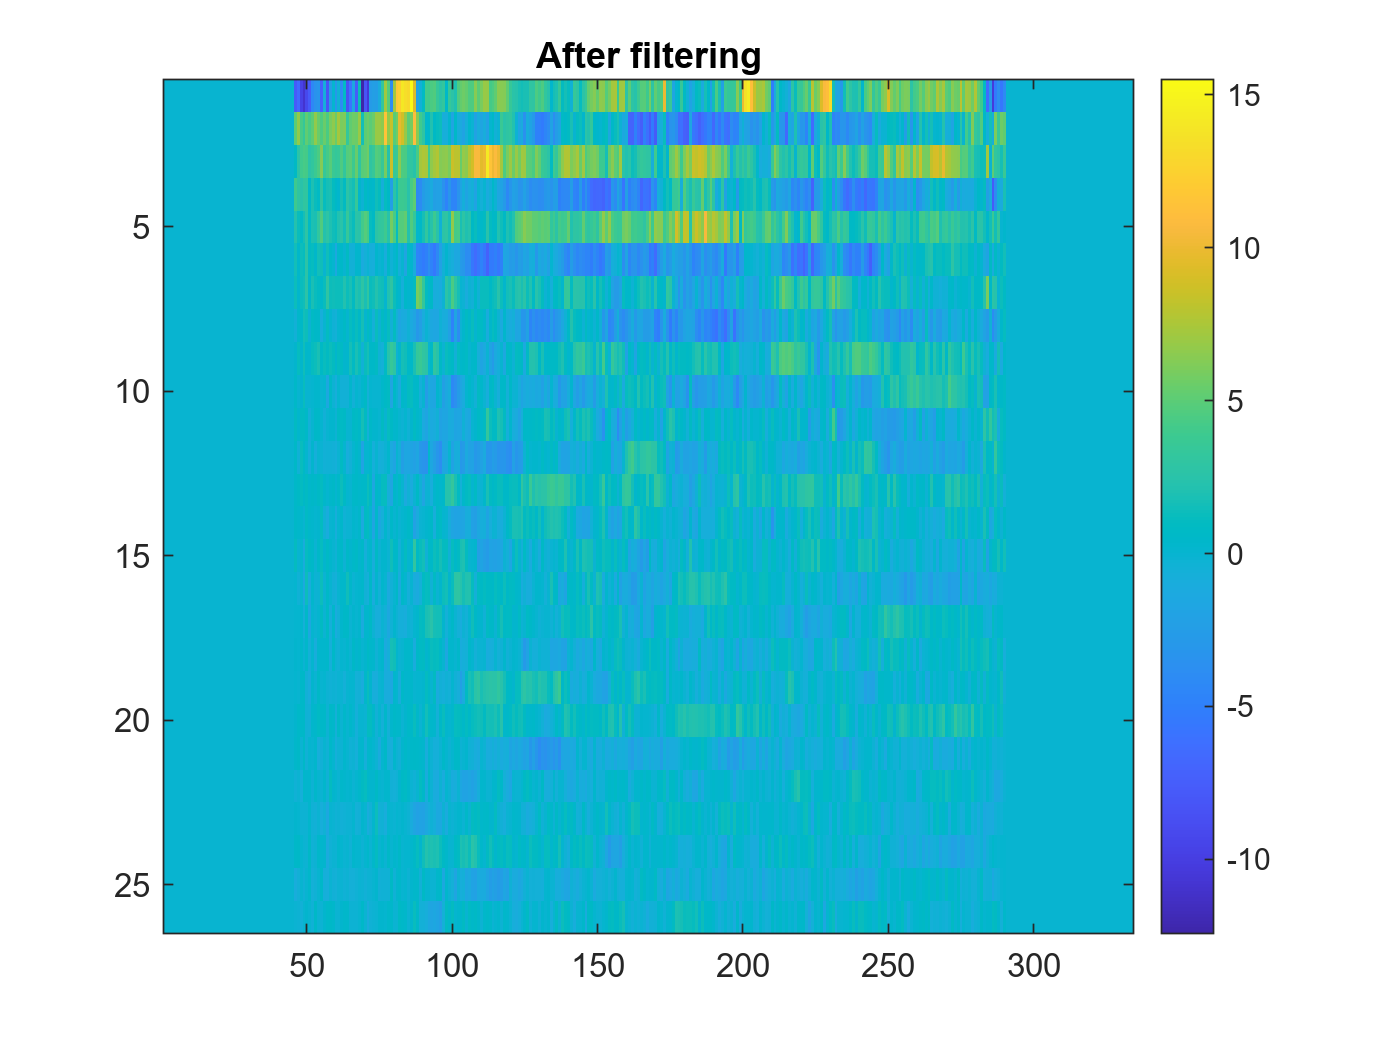

mfcc_coef = my_mfcc(signal, fs, filter_nums, fft_lenght, window_lenght,overlap_percent,ceps_num);


figure;
imagesc(mfcc_coef);
title('After filtering');
colorbar;

#### question 9:

train_dir    = 'dataset/train/';
n           = 88;
code        = train(train_dir, n,filter_nums, fft_lenght,window_lenght_sec,overlap_percent,ceps_num);

dataset/train/s1.wav
dataset/train/s2.wav
dataset/train/s3.wav
dataset/train/s4.wav
dataset/train/s5.wav
dataset/train/s6.wav
dataset/train/s7.wav
dataset/train/s8.wav
dataset/train/s9.wav
dataset/train/s10.wav
dataset/train/s11.wav
dataset/train/s12.wav
dataset/train/s13.wav
dataset/train/s14.wav
dataset/train/s15.wav
dataset/train/s16.wav
dataset/train/s17.wav
dataset/train/s18.wav
dataset/train/s19.wav
dataset/train/s20.wav
dataset/train/s21.wav
dataset/train/s22.wav
dataset/train/s23.wav
dataset/train/s24.wav
dataset/train/s25.wav
dataset/train/s26.wav
dataset/train/s27.wav
dataset/train/s28.wav
dataset/train/s29.wav
dataset/train/s30.wav
dataset/train/s31.wav
dataset/train/s32.wav
dataset/train/s33.wav
dataset/train/s34.wav
dataset/train/s35.wav
dataset/train/s36.wav
dataset/train/s37.wav
dataset/train/s38.wav
dataset/train/s39.wav
dataset/train/s40.wav
dataset/train/s41.wav
dataset/train/s42.wav
dataset/train/s43.wav
dataset/train/s44.wav
dataset/train/s45.wav
dataset/train/s46.w


test_dir     = 'dataset/test/';


#### question 10:

Speaker recognizer:

acc = 0;
for k = 1:20
    f = sprintf('%ss%d.wav', test_dir, k);
    [x, fs] = audioread(f);

    mfcc = my_mfcc(x, fs, filter_nums, fft_lenght, floor(fs*window_lenght_sec), overlap_percent, ceps_num);

    d = zeros(n, 1);
    for i = 1:n
        dist = disteu(mfcc, code{i});
        d(i) = mean(min(dist, [], 2).^2);
    end

    [~, idx] = min(d);
    if k == idx
        acc = acc + 1/20;
    end

    fprintf("Test file %d identified as speaker %d.\n", k, idx);
end

Test file 1 identified as speaker 1.
Test file 2 identified as speaker 2.
Test file 3 identified as speaker 3.
Test file 4 identified as speaker 4.
Test file 5 identified as speaker 71.
Test file 6 identified as speaker 6.
Test file 7 identified as speaker 7.
Test file 8 identified as speaker 8.
Test file 9 identified as speaker 9.
Test file 10 identified as speaker 10.
Test file 11 identified as speaker 11.
Test file 12 identified as speaker 12.
Test file 13 identified as speaker 13.
Test file 14 identified as speaker 14.
Test file 15 identified as speaker 15.
Test file 16 identified as speaker 16.
Test file 17 identified as speaker 17.
Test file 18 identified as speaker 18.
Test file 19 identified as speaker 19.
Test file 20 identified as speaker 20.


fprintf("Model's accuarcy: :%f\n", acc);

Model's accuarcy: :0.950000


#### question 11:


filter_nums = 40;
fft_lenght = 512;
window_lenght_sec = 0.015;
window_lenght = floor(44100*window_lenght_sec);
overlap_percent = 40;
ceps_num = 26;
f = sprintf('%ss%d.wav', test_dir, 8);
[s8, fs] = audioread(f);
win = hamming(1024,"periodic");
NFFT = 1024;
ovlp = 75;

for alpha = 0.1 : 0.1 : 2  % Steps from 1 to 10 in increments of 2
    x = phaseVocoder(s8, NFFT, ovlp, win, alpha);
    mfcc = my_mfcc(x, fs, filter_nums, fft_lenght, floor(fs*window_lenght_sec), overlap_percent, ceps_num);

    d = zeros(n, 1);
    for i = 1:n
        dist = disteu(mfcc, code{i});
        d(i) = mean(min(dist, [], 2).^2);
    end

    [~, idx] = min(d);
  
    

    fprintf("Test file :8 with alpha=%d,identified as speaker %d.\n", alpha ,id);
    
end

Test file :8 with alpha=1.000000e-01,identified as speaker 8.
Test file :8 with alpha=2.000000e-01,identified as speaker 8.
Test file :8 with alpha=3.000000e-01,identified as speaker 8.
Test file :8 with alpha=4.000000e-01,identified as speaker 8.
Test file :8 with alpha=5.000000e-01,identified as speaker 8.
Test file :8 with alpha=6.000000e-01,identified as speaker 8.
Test file :8 with alpha=7.000000e-01,identified as speaker 8.
Test file :8 with alpha=8.000000e-01,identified as speaker 8.
Test file :8 with alpha=9.000000e-01,identified as speaker 8.
Test file :8 with alpha=1,identified as speaker 8.
Test file :8 with alpha=1.100000e+00,identified as speaker 8.
Test file :8 with alpha=1.200000e+00,identified as speaker 8.
Test file :8 with alpha=1.300000e+00,identified as speaker 8.
Test file :8 with alpha=1.400000e+00,identified as speaker 8.
Test file :8 with alpha=1.500000e+00,identified as speaker 8.
Test file :8 with alpha=1.600000e+00,identified as speaker 8.
Test file :8 with a

as we can see it works perfectly well for all of alpha values

#### Bonus Part:

snr_levels = [0 5 10 15 20 30];
accuracies = zeros(size(snr_levels));

train_dir = 'dataset/train/';
testdir  = 'dataset/test/';
n        = 88;

for s = 1:length(snr_levels)
    snr_db = snr_levels(s);
    fprintf("\n Running for SNR = %d dB \n", snr_db);

    noisy_dir = 'dataset/noisy_train/';
    if ~exist(noisy_dir, 'dir')
        mkdir(noisy_dir);
    end
   
    for i = 1:n
        filename = sprintf('%ss%d.wav', train_dir, i);
        %disp(filename);
    
       
        
        [sig, fs] = audioread(filename);
        

        signal_power = mean(sig.^2);
        snr_linear = 10^(snr_db / 10);
        noise_power = signal_power / snr_linear;
        noise = sqrt(noise_power) * randn(size(sig));
        noisy_sig = sig + noise;
        
        noisy_filename = sprintf('%ss%d.wav', noisy_dir, i);
        audiowrite(noisy_filename, noisy_sig, fs);
    end

    code = train(noisy_dir, n, filter_nums, fft_lenght, window_lenght_sec, overlap_percent, ceps_num);

    acc = 0;
    for k = 1:20
        test_file = sprintf('%ss%d.wav', testdir, k);
        [test_signal, fs_test] = audioread(test_file);

        mfcc_coef_test = my_mfcc(test_signal, fs_test, filter_nums, fft_lenght, ...
                                 floor(fs_test*window_lenght_sec), overlap_percent, ceps_num);

        all_distortions = zeros(n,1);
        for i=1:n
            dis = disteu(mfcc_coef_test, code{i});
            distortion = mean(min(dis, [], 2).^2);
            all_distortions(i) = distortion;
        end
        min_index = find(all_distortions == min(all_distortions));

        if(k == min_index)
            acc = acc + (1/10);
        end
    end
    accuracies(s) = acc;
    fprintf("Accuracy at %d dB SNR: %.2f%%\n", snr_db, acc*100);
end


 Running for SNR = 0 dB 


dataset/noisy_train/s1.wav
dataset/noisy_train/s2.wav
dataset/noisy_train/s3.wav
dataset/noisy_train/s4.wav
dataset/noisy_train/s5.wav
dataset/noisy_train/s6.wav
dataset/noisy_train/s7.wav
dataset/noisy_train/s8.wav
dataset/noisy_train/s9.wav
dataset/noisy_train/s10.wav
dataset/noisy_train/s11.wav
dataset/noisy_train/s12.wav
dataset/noisy_train/s13.wav
dataset/noisy_train/s14.wav
dataset/noisy_train/s15.wav
dataset/noisy_train/s16.wav
dataset/noisy_train/s17.wav
dataset/noisy_train/s18.wav
dataset/noisy_train/s19.wav
dataset/noisy_train/s20.wav
dataset/noisy_train/s21.wav
dataset/noisy_train/s22.wav
dataset/noisy_train/s23.wav
dataset/noisy_train/s24.wav
dataset/noisy_train/s25.wav
dataset/noisy_train/s26.wav
dataset/noisy_train/s27.wav
dataset/noisy_train/s28.wav
dataset/noisy_train/s29.wav
dataset/noisy_train/s30.wav
dataset/noisy_train/s31.wav
dataset/noisy_train/s32.wav
dataset/noisy_train/s33.wav
dataset/noisy_train/s34.wav
dataset/noisy_train/s35.wav
dataset/noisy_train/s36.wav
d

Accuracy at 0 dB SNR: 0.00%



 Running for SNR = 5 dB 


dataset/noisy_train/s1.wav
dataset/noisy_train/s2.wav
dataset/noisy_train/s3.wav
dataset/noisy_train/s4.wav
dataset/noisy_train/s5.wav
dataset/noisy_train/s6.wav
dataset/noisy_train/s7.wav
dataset/noisy_train/s8.wav
dataset/noisy_train/s9.wav
dataset/noisy_train/s10.wav
dataset/noisy_train/s11.wav
dataset/noisy_train/s12.wav
dataset/noisy_train/s13.wav
dataset/noisy_train/s14.wav
dataset/noisy_train/s15.wav
dataset/noisy_train/s16.wav
dataset/noisy_train/s17.wav
dataset/noisy_train/s18.wav
dataset/noisy_train/s19.wav
dataset/noisy_train/s20.wav
dataset/noisy_train/s21.wav
dataset/noisy_train/s22.wav
dataset/noisy_train/s23.wav
dataset/noisy_train/s24.wav
dataset/noisy_train/s25.wav
dataset/noisy_train/s26.wav
dataset/noisy_train/s27.wav
dataset/noisy_train/s28.wav
dataset/noisy_train/s29.wav
dataset/noisy_train/s30.wav
dataset/noisy_train/s31.wav
dataset/noisy_train/s32.wav
dataset/noisy_train/s33.wav
dataset/noisy_train/s34.wav
dataset/noisy_train/s35.wav
dataset/noisy_train/s36.wav
d

Accuracy at 5 dB SNR: 0.00%



 Running for SNR = 10 dB 


dataset/noisy_train/s1.wav
dataset/noisy_train/s2.wav
dataset/noisy_train/s3.wav
dataset/noisy_train/s4.wav
dataset/noisy_train/s5.wav
dataset/noisy_train/s6.wav
dataset/noisy_train/s7.wav
dataset/noisy_train/s8.wav
dataset/noisy_train/s9.wav
dataset/noisy_train/s10.wav
dataset/noisy_train/s11.wav
dataset/noisy_train/s12.wav
dataset/noisy_train/s13.wav
dataset/noisy_train/s14.wav
dataset/noisy_train/s15.wav
dataset/noisy_train/s16.wav
dataset/noisy_train/s17.wav
dataset/noisy_train/s18.wav
dataset/noisy_train/s19.wav
dataset/noisy_train/s20.wav
dataset/noisy_train/s21.wav
dataset/noisy_train/s22.wav
dataset/noisy_train/s23.wav
dataset/noisy_train/s24.wav
dataset/noisy_train/s25.wav
dataset/noisy_train/s26.wav
dataset/noisy_train/s27.wav
dataset/noisy_train/s28.wav
dataset/noisy_train/s29.wav
dataset/noisy_train/s30.wav
dataset/noisy_train/s31.wav
dataset/noisy_train/s32.wav
dataset/noisy_train/s33.wav
dataset/noisy_train/s34.wav
dataset/noisy_train/s35.wav
dataset/noisy_train/s36.wav
d

Accuracy at 10 dB SNR: 0.00%



 Running for SNR = 15 dB 


dataset/noisy_train/s1.wav
dataset/noisy_train/s2.wav
dataset/noisy_train/s3.wav
dataset/noisy_train/s4.wav
dataset/noisy_train/s5.wav
dataset/noisy_train/s6.wav
dataset/noisy_train/s7.wav
dataset/noisy_train/s8.wav
dataset/noisy_train/s9.wav
dataset/noisy_train/s10.wav
dataset/noisy_train/s11.wav
dataset/noisy_train/s12.wav
dataset/noisy_train/s13.wav
dataset/noisy_train/s14.wav
dataset/noisy_train/s15.wav
dataset/noisy_train/s16.wav
dataset/noisy_train/s17.wav
dataset/noisy_train/s18.wav
dataset/noisy_train/s19.wav
dataset/noisy_train/s20.wav
dataset/noisy_train/s21.wav
dataset/noisy_train/s22.wav
dataset/noisy_train/s23.wav
dataset/noisy_train/s24.wav
dataset/noisy_train/s25.wav
dataset/noisy_train/s26.wav
dataset/noisy_train/s27.wav
dataset/noisy_train/s28.wav
dataset/noisy_train/s29.wav
dataset/noisy_train/s30.wav
dataset/noisy_train/s31.wav
dataset/noisy_train/s32.wav
dataset/noisy_train/s33.wav
dataset/noisy_train/s34.wav
dataset/noisy_train/s35.wav
dataset/noisy_train/s36.wav
d

Accuracy at 15 dB SNR: 0.00%



 Running for SNR = 20 dB 


dataset/noisy_train/s1.wav
dataset/noisy_train/s2.wav
dataset/noisy_train/s3.wav
dataset/noisy_train/s4.wav
dataset/noisy_train/s5.wav
dataset/noisy_train/s6.wav
dataset/noisy_train/s7.wav
dataset/noisy_train/s8.wav
dataset/noisy_train/s9.wav
dataset/noisy_train/s10.wav
dataset/noisy_train/s11.wav
dataset/noisy_train/s12.wav
dataset/noisy_train/s13.wav
dataset/noisy_train/s14.wav
dataset/noisy_train/s15.wav
dataset/noisy_train/s16.wav
dataset/noisy_train/s17.wav
dataset/noisy_train/s18.wav
dataset/noisy_train/s19.wav
dataset/noisy_train/s20.wav
dataset/noisy_train/s21.wav
dataset/noisy_train/s22.wav
dataset/noisy_train/s23.wav
dataset/noisy_train/s24.wav
dataset/noisy_train/s25.wav
dataset/noisy_train/s26.wav
dataset/noisy_train/s27.wav
dataset/noisy_train/s28.wav
dataset/noisy_train/s29.wav
dataset/noisy_train/s30.wav
dataset/noisy_train/s31.wav
dataset/noisy_train/s32.wav
dataset/noisy_train/s33.wav
dataset/noisy_train/s34.wav
dataset/noisy_train/s35.wav
dataset/noisy_train/s36.wav
d

Accuracy at 20 dB SNR: 30.00%



 Running for SNR = 30 dB 


dataset/noisy_train/s1.wav
dataset/noisy_train/s2.wav
dataset/noisy_train/s3.wav
dataset/noisy_train/s4.wav
dataset/noisy_train/s5.wav
dataset/noisy_train/s6.wav
dataset/noisy_train/s7.wav
dataset/noisy_train/s8.wav
dataset/noisy_train/s9.wav
dataset/noisy_train/s10.wav
dataset/noisy_train/s11.wav
dataset/noisy_train/s12.wav
dataset/noisy_train/s13.wav
dataset/noisy_train/s14.wav
dataset/noisy_train/s15.wav
dataset/noisy_train/s16.wav
dataset/noisy_train/s17.wav
dataset/noisy_train/s18.wav
dataset/noisy_train/s19.wav
dataset/noisy_train/s20.wav
dataset/noisy_train/s21.wav
dataset/noisy_train/s22.wav
dataset/noisy_train/s23.wav
dataset/noisy_train/s24.wav
dataset/noisy_train/s25.wav
dataset/noisy_train/s26.wav
dataset/noisy_train/s27.wav
dataset/noisy_train/s28.wav
dataset/noisy_train/s29.wav
dataset/noisy_train/s30.wav
dataset/noisy_train/s31.wav
dataset/noisy_train/s32.wav
dataset/noisy_train/s33.wav
dataset/noisy_train/s34.wav
dataset/noisy_train/s35.wav
dataset/noisy_train/s36.wav
d

Accuracy at 30 dB SNR: 50.00%


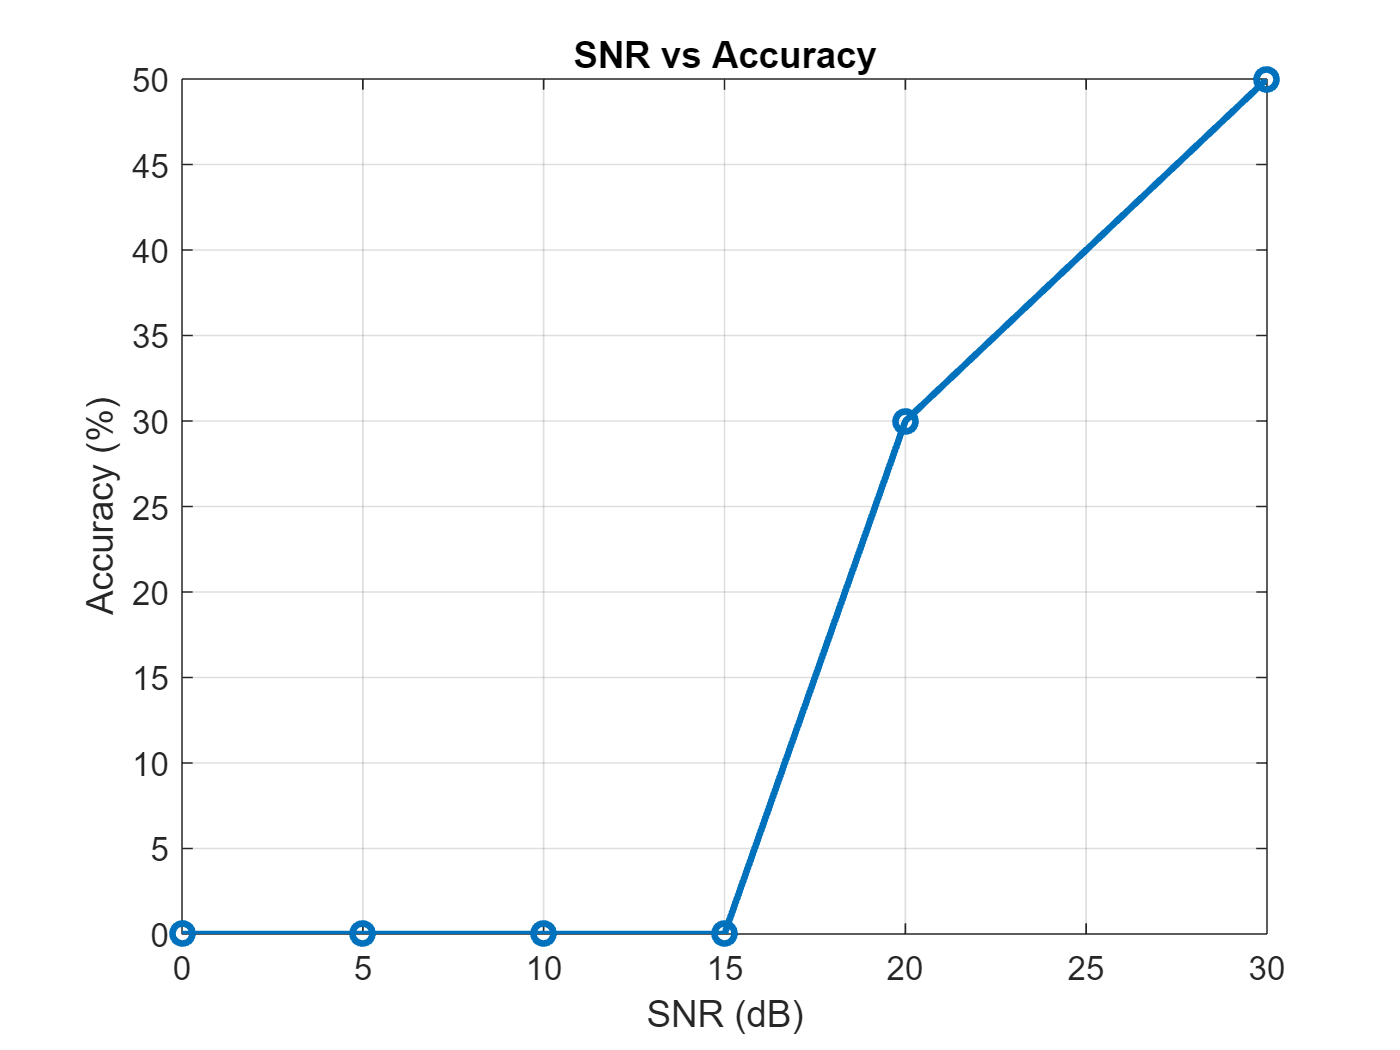

figure;
plot(snr_levels, accuracies*100, '-o', 'LineWidth', 2);
xlabel('SNR (dB)');
ylabel('Accuracy (%)');
title('SNR vs Accuracy');
grid on;

## MFCC function

function out = my_mfcc(x, fs, f_num, fft_len, win_len, overlap, cep_num)

    x = filter([1 -0.97], 1, x);
    hop = floor(((100 - overlap)/100) * win_len);
    N = 1 + ceil((length(x) - win_len) / hop);

    bank = melfb(f_num, fft_len, fs);
    spec = zeros(N, f_num);

    for i = 1:N
        frm = zeros(win_len, 1);
        if i == N
            temp = x((i-1)*hop + 1:end);
            frm(1:length(temp)) = temp;
        else
            frm = x((i-1)*hop + 1:(i-1)*hop + win_len);
        end
        fft_out = fft(frm, fft_len);
        pow = abs(fft_out(1:fft_len/2+1)).^2;
        for j = 1:f_num
            spec(i,j) = sum(pow' .* bank(j,:));
        end
    end

    spec(spec == 0) = eps;
    spec = log(spec);

    ceps = zeros(N, f_num);
    for i = 1:N
        ceps(i,:) = dct(spec(i,:));
    end

    out = ceps';
    out = out(2:cep_num+1, :);
end


## VQLBG

function cb = vqlbg(x, K)

    eps_val = 0.01;
    tol = 1e-3;

    cb = mean(x, 2);
    curr_size = 1;

    while curr_size < K
        tmp = zeros(size(cb,1), curr_size*2);
        for i = 1:curr_size
            tmp(:,2*i-1) = cb(:,i) * (1 + eps_val);
            tmp(:,2*i)   = cb(:,i) * (1 - eps_val);
        end
        cb = tmp;
        curr_size = 2 * curr_size;

        d_prev = Inf;
        while true
            dists = disteu(x, cb);
            [~, idx] = min(dists, [], 2);
            for j = 1:curr_size
                vecs = x(:, idx == j);
                if ~isempty(vecs)
                    cb(:,j) = mean(vecs, 2);
                end
            end

            d_now = mean(min(dists, [], 2).^2);
            if abs(d_prev - d_now)/d_prev < tol || d_now == 0
                break
            end
            d_prev = d_now;
        end
    end
end


## Melfb

function m = melfb(p, n, fs)
    % MELFB         Determine matrix for a mel-spaced filterbank
    %
    % Inputs:       p   number of filters in filterbank
    %               n   length of fft
    %               fs  sample rate in Hz
    %
    % Outputs:      x   a (sparse) matrix containing the filterbank amplitudes
    %                   size(x) = [p, 1+floor(n/2)]
    %
    % Usage:        For example, to compute the mel-scale spectrum of a
    %               colum-vector signal s, with length n and sample rate fs:
    %
    %               f = fft(s);
    %               m = melfb(p, n, fs);
    %               n2 = 1 + floor(n/2);
    %               z = m * abs(f(1:n2)).^2;
    %
    %               z would contain p samples of the desired mel-scale spectrum
    %
    %               To plot filterbanks e.g.:
    %
    %               plot(linspace(0, (12500/2), 129), melfb(20, 256, 12500)'),
    %               title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
    
    f0 = 700 / fs;
    fn2 = floor(n/2);
    
    lr = log(1 + 0.5/f0) / (p+1);
    
    % convert to fft bin numbers with 0 for DC term
    bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1));
    
    b1 = floor(bl(1)) + 1;
    b2 = ceil(bl(2));
    b3 = floor(bl(3));
    b4 = min(fn2, ceil(bl(4))) - 1;
    
    pf = log(1 + (b1:b4)/n/f0) / lr;
    fp = floor(pf);
    pm = pf - fp;
    
    r  = [fp(b2:b4) 1+fp(1:b3)];
    c  = [b2:b4 1:b3] + 1;
    v  = 2 * [1-pm(b2:b4) pm(1:b3)];
    
    m  = sparse(r, c, v, p, 1+fn2);
end

## Distance Calculator

function d = disteu(x, y)
    % DISTEU Pairwise Euclidean distances between columns of two matrices
    %
    % Input:
    %       x, y:   Two matrices whose each column is an a vector data.
    %
    % Output:
    %       d:      Element d(i,j) will be the Euclidean distance between two
    %               column vectors X(:,i) and Y(:,j)
    %
    % Note:
    %       The Euclidean distance D between two vectors X and Y is:
    %       D = sum((x-y).^2).^0.5
    
    [M, N]  = size(x);
    [M2, P] = size(y); 
    
    if (M ~= M2)
        error('Matrix dimensions do not match.')
    end
    
    d       = zeros(N, P);
    
    if (N < P)
        copies = zeros(1,P);
        for n = 1:N
            d(n,:) = sum((x(:, n+copies) - y) .^2, 1);
        end
    else
        copies = zeros(1,N);
        for p = 1:P
            d(:,p) = sum((x - y(:, p+copies)) .^2, 1)';
        end
    end
    
    d       = d.^0.5;
end

## Train 

function code = train(train_dir, n, f_num, fft_len, win_sec, overlap, cep_num)

    k = 64;

    for i = 1:n
        file = sprintf('%ss%d.wav', train_dir, i);
        disp(file);

        [x, fs] = audioread(file);
        x = x / rms(x);
        win_len = floor(fs * win_sec);
        mfcc = my_mfcc(x, fs, f_num, fft_len,win_len , overlap, cep_num);
        
        code{i} = vqlbg(mfcc, k);
    end
end

## Phase Vocoder Algorithm

function y = phaseVocoder(x, Nfft, ovlp, win, alpha)

    X = calcSTFT(x, Nfft, ovlp, win);
    Xmag = abs(X);
    Xph = angle(X);

    winLen = length(win);
    sigLen = length(x);
    hop = (1 - ovlp/100) * winLen;
    nFrames = 1 + ceil((sigLen - winLen)/hop);
    synHop = alpha * hop;

    dph = diff(Xph, 1, 2);
    binFreqs = 2 * pi * (0:Nfft-1)' / Nfft;
    expected = binFreqs * hop;
    delta = unwrap(dph - expected, pi, 2);
    trueFreqs = expected + delta;

    Yph = zeros(size(Xph));
    Yph(:,1) = Xph(:,1);
    for i = 2:nFrames-1
        Yph(:,i) = Yph(:,i-1) + (synHop/2)*(trueFreqs(:,i-1) + trueFreqs(:,i));
    end
    Yph(:,nFrames) = Yph(:,nFrames-1) + synHop * trueFreqs(:,nFrames-1);

    Y = Xmag .* exp(1j * Yph);

    nHops = ceil(winLen / synHop);
    bufLen = winLen + nHops * round(synHop);
    denomBuf = zeros(bufLen, 1);
    for n = 0:nHops
        idx1 = n * round(synHop) + 1;
        idx2 = idx1 + winLen - 1;
        if idx2 <= bufLen
            denomBuf(idx1:idx2) = denomBuf(idx1:idx2) + win.^2;
        end
    end
    winCorr = denomBuf(1:winLen);
    winSyn = (1/Nfft) * win ./ winCorr;

    y = zeros(round(sigLen*alpha), 1);
    for i = 1:nFrames
        frame = real(ifft(Y(:,i), Nfft));
        wFrame = frame .* winSyn;
        pos1 = round((i-1)*synHop) + 1;
        pos2 = pos1 + winLen - 1;
        if pos2 <= length(y)
            y(pos1:pos2) = y(pos1:pos2) + wFrame;
        end
    end
end

## Calculating Short-Time Fourier Transform

function out = calcSTFT(x, Nfft, overlap, window)
    winLen = length(window);
    sigLen = length(x);
    hop = (1 - overlap/100) * winLen;
    nFrames = ceil((sigLen - winLen) / hop) + 1;
    
    out = zeros(winLen, nFrames);
    for k = 1:nFrames
        idx_start = round((k-1)*hop) + 1;
        idx_end = idx_start + winLen - 1;
        if idx_end > sigLen
            segment = x(idx_start:end) .* window(1:(sigLen - idx_start + 1));
        else
            segment = x(idx_start:idx_end) .* window;
        end
        out(:,k) = fft(segment, Nfft);
    end
end

# Questions

#### question 6:

in the MFCC function part

#### question 7:

in the first part of the code

#### question 8:

in the vqlb function

#### question 9:

marked in the main code

#### question 10:

marked in the main code

#### qustion 11: